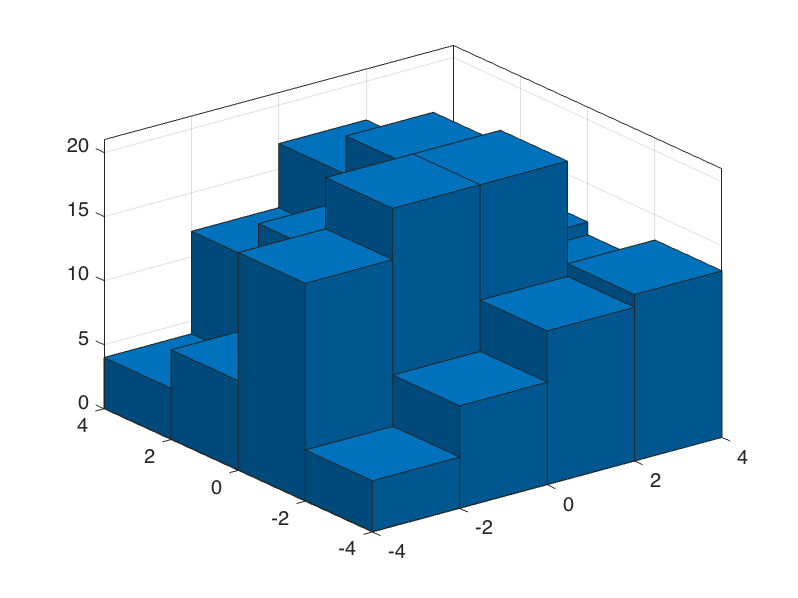

data = dlmread('map_0.log');
n = 200;
X = rand(2,n)*2*pi-pi;
colpicked = randsample(1:40000,n);
Y = [data(4,colpicked);data(5,colpicked)]; 
histogram2(X(1,:),X(2,:));

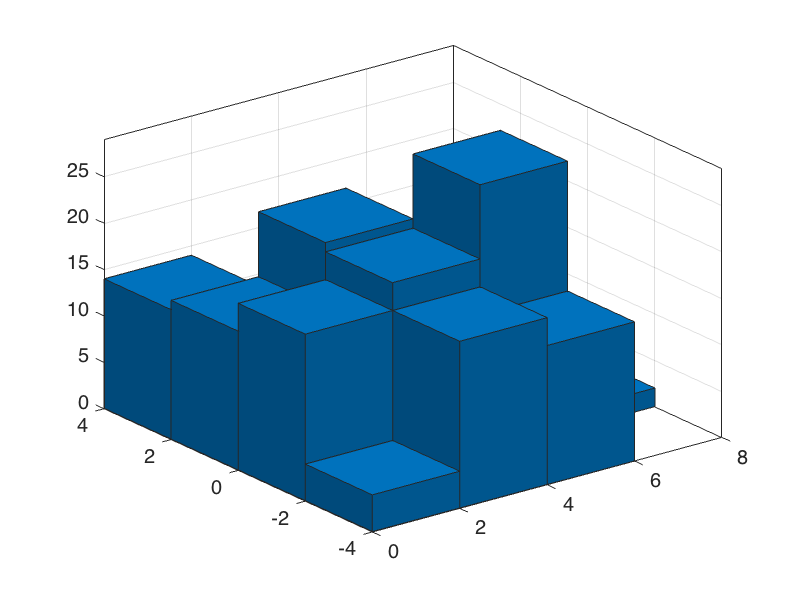

histogram2(Y(1,:),X(2,:));

C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = norm(Y(:,i)-X(:,j))^2;
    end
end
r = ones(n,1)/n;
c = ones(n,1)/n;
X0 = r*c';

## Optimal solution

f = reshape(C,[n^2,1]);
x_vec = reshape(X0,[n^2,1]);
A = zeros(2*n,n^2);
for i = 1:n
    A(1:n,(i-1)*n+1:i*n) = speye(n);
    A(n+i,(i-1)*n+1:i*n) = ones(1,n);
end
A = sparse(A);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Sinkhorn

epsilon = [10,100];
maxiter = 300000;
time_sink = zeros(maxiter/100 + 1,2);
feas_sink = zeros(maxiter/100 + 1,2);
fval_sink = zeros(maxiter/100 + 1,2);
for num = 1:2
    if num == 1
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X1_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter);
    else
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X2_sink] = Sinkhorn(r,c,epsilon(num),C,f_opt,maxiter);
    end
end

k = 1000, accuracy = 0.35584
k = 2000, accuracy = 0.35584
k = 3000, accuracy = 0.35584
k = 4000, accuracy = 0.35584
k = 5000, accuracy = 0.35584
k = 6000, accuracy = 0.35584
k = 7000, accuracy = 0.35584
k = 8000, accuracy = 0.35584
k = 9000, accuracy = 0.35584
k = 10000, accuracy = 0.35584
k = 11000, accuracy = 0.35584
k = 12000, accuracy = 0.35584
k = 13000, accuracy = 0.35584
k = 14000, accuracy = 0.35584
k = 15000, accuracy = 0.35584
k = 16000, accuracy = 0.35584
k = 17000, accuracy = 0.35584
k = 18000, accuracy = 0.35584
k = 19000, accuracy = 0.35584
k = 20000, accuracy = 0.35584
k = 21000, accuracy = 0.35584
k = 22000, accuracy = 0.35584
k = 23000, accuracy = 0.35584
k = 24000, accuracy = 0.35584
k = 25000, accuracy = 0.35584
k = 26000, accuracy = 0.35584
k = 27000, accuracy = 0.35584
k = 28000, accuracy = 0.35584
k = 29000, accuracy = 0.35584
k = 30000, accuracy = 0.35584
k = 31000, accuracy = 0.35584
k = 32000, accuracy = 0.35584
k = 33000, accuracy = 0.35584
k = 34000, accuracy

k = 1000, accuracy = 2.9757
k = 2000, accuracy = 2.9757
k = 3000, accuracy = 2.9757
k = 4000, accuracy = 2.9757
k = 5000, accuracy = 2.9757
k = 6000, accuracy = 2.9757
k = 7000, accuracy = 2.9757
k = 8000, accuracy = 2.9757
k = 9000, accuracy = 2.9757
k = 10000, accuracy = 2.9757
k = 11000, accuracy = 2.9757
k = 12000, accuracy = 2.9757
k = 13000, accuracy = 2.9757
k = 14000, accuracy = 2.9757
k = 15000, accuracy = 2.9757
k = 16000, accuracy = 2.9757
k = 17000, accuracy = 2.9757
k = 18000, accuracy = 2.9757
k = 19000, accuracy = 2.9757
k = 20000, accuracy = 2.9757
k = 21000, accuracy = 2.9757
k = 22000, accuracy = 2.9757
k = 23000, accuracy = 2.9757
k = 24000, accuracy = 2.9757
k = 25000, accuracy = 2.9757
k = 26000, accuracy = 2.9757
k = 27000, accuracy = 2.9757
k = 28000, accuracy = 2.9757
k = 29000, accuracy = 2.9757
k = 30000, accuracy = 2.9757
k = 31000, accuracy = 2.9757
k = 32000, accuracy = 2.9757
k = 33000, accuracy = 2.9757
k = 34000, accuracy = 2.9757
k = 35000, accuracy = 2

## Accelerated RBCD

maxiter = 5000;
M = 40

M = 40

[fval_arbcd,time_arbcd,feas_arbcd,X2,card_arbcd] = ARBCD(r,c,n,X1,f_opt,C,M,maxiter,1);

iter = 1000, accuracy = 0.012946
iter = 2000, accuracy = 0.007747
iter = 3000, accuracy = 0.006436
iter = 4000, accuracy = 0.0060666
iter = 5000, accuracy = 0.005717
number of successful iterations =5000


## Plot

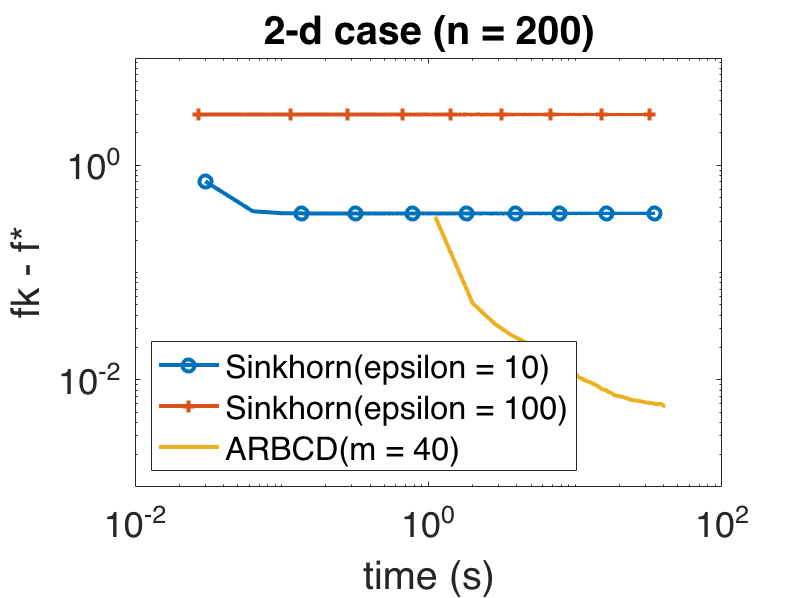

figure
loglog(time_sink(:,1),fval_sink(:,1),'-o','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,2),fval_sink(:,2),'-+','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_arbcd,fval_arbcd,'LineWidth',2)
xlim([1e-2 1e2])
legend('Sinkhorn(epsilon = 10)','Sinkhorn(epsilon = 100)','ARBCD(m = 40)','location','southwest')
title('2-d case (n = 200)')
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',18)